clear
close all
hold off

%Vamos a representar cómo se mueve el centro de la formación

N=5; %Número de robots, uno adicional en el centro de la formación
%Desviación estándar es v=2
v=2;
%Desviación en la formación de robots es delta=0.1
delta=0.1;
iteration=200; %Número de iteraciones
step_size=0.1;
D=5; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0_initial=[20;20]; %Posición del centro inicial (initial guess)
r0=[0 0]'; %Centro de contaminación
e=[1;0];
a=0.01;

w0=1; %Movimiento circular de un radián por segundo

colors=["ob","ok","or","oy","og","om","oc","ob"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0_initial;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
simulation=100; %número de simulaciones
mod_rc=zeros(iteration,simulation);
pos_rob=zeros(2,N,iteration);
i=1;
mod_r_c(1)=norm(c0_initial-r0);

for k=1:100
    c0=c0_initial;
    K=0;
    for i=2:iteration
        H = Hessiano_error(c0,t(i),N,D,S,w0,v,delta);
        grad_centr=-gradient_point2D_ruido(c0,t(i),N,D,S,w0,v,delta);
        %En caso de que el Hessiano no esté bien condicionado, se invierte la
        %matriz identidad
        if (all(eig(H) < 0) && cond(H)<1/a)
            H_inv=inv(H);
        else
            H_inv=inv(-eye(2));
        end
        %Aplicación de la aproximación por el Hessiano
        c(:,i)=c0-step_size*H_inv*grad_centr;
        if norm(c(:,i)-r0)>mod_r_c(i-1)
            c(:,i)=c0+step_size*grad_centr;
        end
        %Hay un nuevo centro alrededor del cual se tienen que poner los robots
        c0=c(:,i);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
        mod_r_c(i)=norm(c0-r0);
    end
    mod_rc(:,k)=mod_r_c;
end

Representación de la media y la desviación estándar:

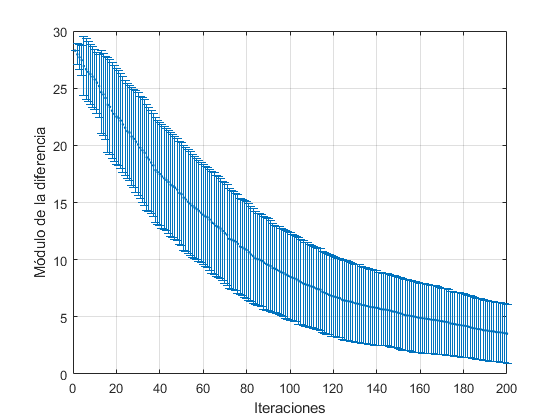

for h=1:iteration
    media(h)=mean(mod_rc(h,:));
    desv_std(h)=std(mod_rc(h,:));
end
errorbar(1:iteration,media,desv_std,'.')
xlabel('Iteraciones')
ylabel('Módulo de la diferencia')
grid on

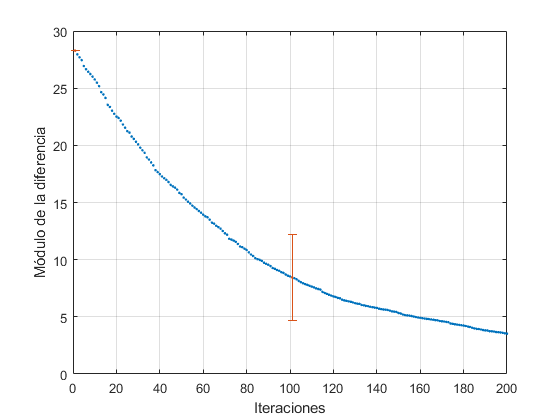


plot(1:iteration,media,'.')
hold on
puntos=1:100:iteration;
errorbar(puntos,media(puntos),desv_std(puntos),'.')
xlabel('Iteraciones')
ylabel('Módulo de la diferencia')
grid on

media(iteration)

ans = 3.5288